# MPC tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 8 parallel workers

## Define optimization variables

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-3, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-2, 1], 'Transform', 'log');

% lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [lambda_z, lambda_o, lambda];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.


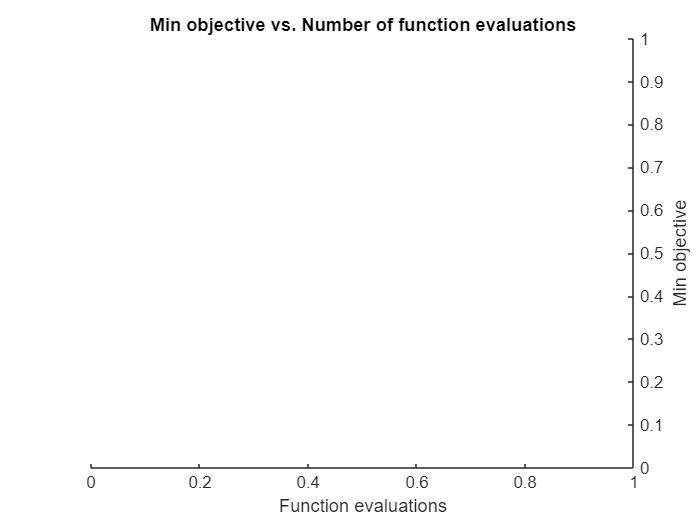

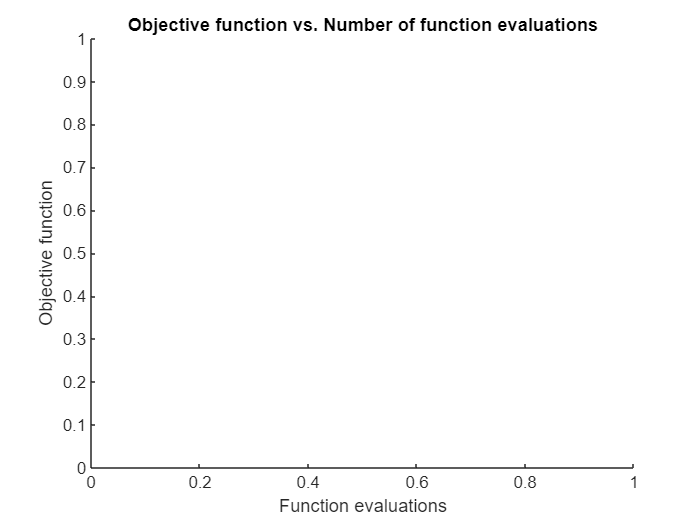

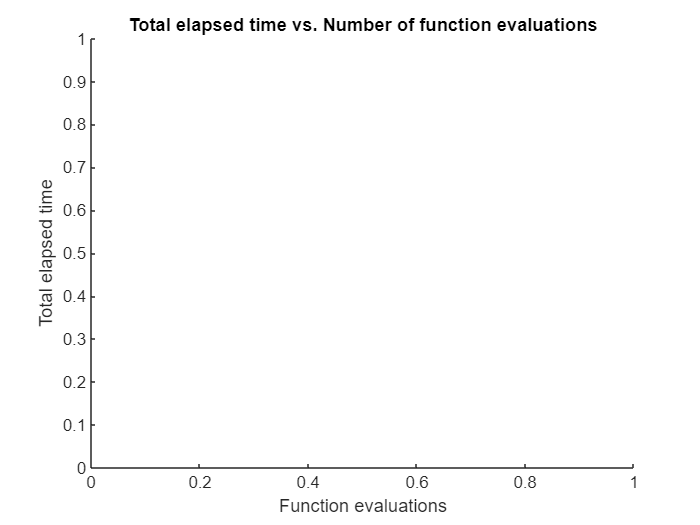

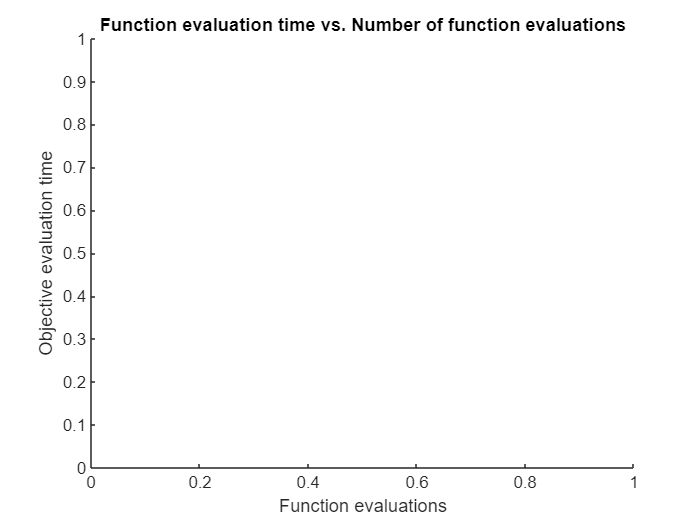

General Error occurred in WebControllerFactory::create()


NumSeedPoints = 2*p.NumWorkers;
lb = log10([1e-5, 1e-5, 1e-5]);
ub = log10([1e-1, 1e-1, 1e-1]);

Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {'lambda_z','lambda_o','lambda'});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   12*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

plotGP(gp, results)

## Sensitivity analysis

Global (trained kernel length scales)

lengthScales = gpGlobalSensitivity(gp)

Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)